# flutterpk.m

Solves dynamic stability of a 2-DoF airfoil using the p-k method. Degrees of freedom are pitch ($\alpha$) and plunge ($h$) in Figure 3.1 below. The flap is not active ($\delta =0$). 

Dependencies:

   ** theodorsen.m:** Analytical expression for Theodorsen's lift deficiency function.

Written by:

    Rafael Palacios (r.palacios@imperial.ac.uk)

Latest update:

     April 2024

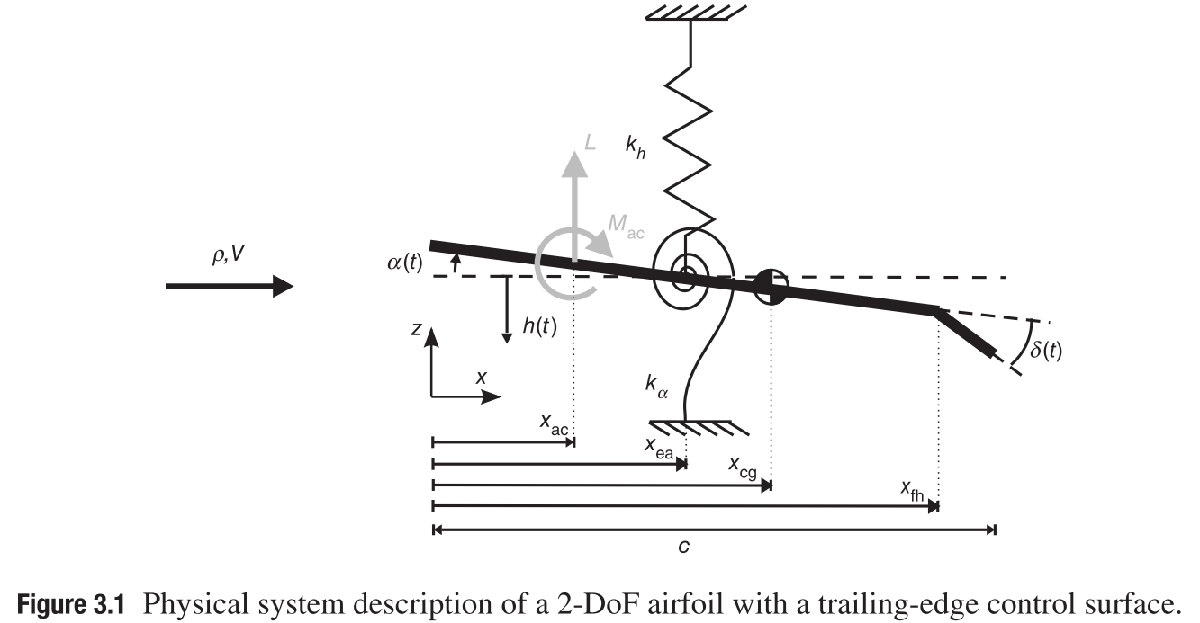

## Parameters

clear all

% Problem constants
rho=1; c=1; omega_a=1;     % Non-dim results are independent of this choice.
mu=5;                      % Mass ratio (m/(pi*rho*c^2)
r_a =0.25*c;               % Radius of gyration (sqrt(I_a/m))
x_ac=0.25*c;               % Coordinate of the aerodynamic centre
x_ea=0.35*c;               % Coordinate of the elastic axis

## Compute aeroelastic matrices for nominal configuration

Default value for problem parameters.

omega_ratio1= 0.5;    % Ratio of plunge/pitch typical frequencies
xalpha1=0.1;          % Nondimensional position of cg (in semichords after the e.a.)

The problem to be solved is

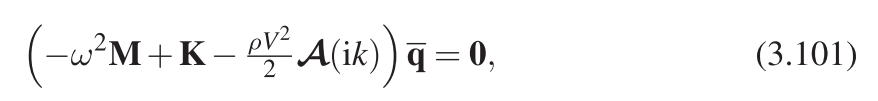

Define structural and inertial coefficients.

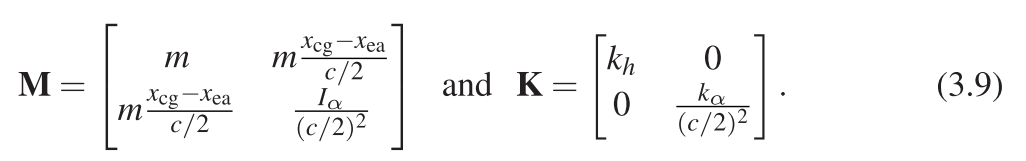

% Derived parameters:
    x_cg   = x_ea+xalpha1*c/2;
    m      = mu*pi*rho*c^2;
    I_a    = m*r_a^2;
    k_a    = I_a*omega_a^2;
    omega_h= omega_ratio1*omega_a;
    k_h    = m * omega_h^2;

% mass matrix and stiffness matrix:
    M=[[m m*(x_cg-x_ea)/(c/2)];[m*(x_cg-x_ea)/(c/2) I_a/(c^2/4)]];
    K=[[k_h 0];[0 k_a/(c^2/4)]];


Define frequency-domain lift and moment coefficients

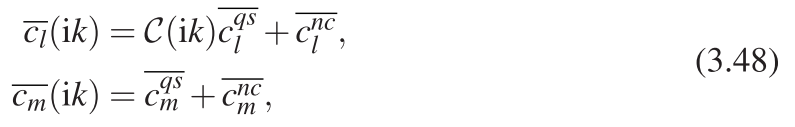

with circulatory and non-circulatory terms given by:

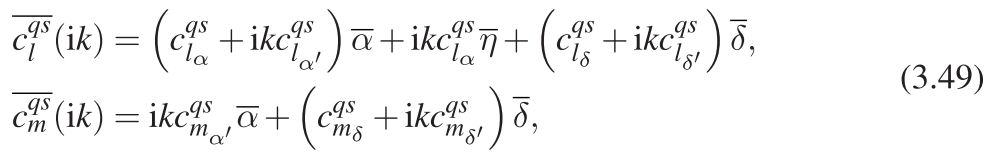

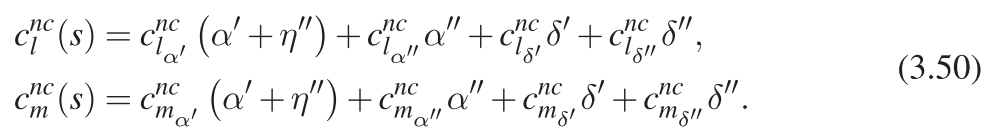

% Nondimensional axis of pitch rotation
    nu_ea  = (x_ea-c/2)/(c/2);

% Aerodynamic coefficients for a flat plate.
    CLa0qs=2*pi;
    CLa1qs=2*pi*(1/2-nu_ea);
    CMa1qs=-pi/4;
    CLa1nc=pi;
    CLa2nc=-pi*nu_ea;
    CMa1nc=-pi/4;
    CMa2nc=-pi/4*(1/4-nu_ea);

% Aerodynamic influence coefficient matrices:
    A_0 = [[0 CLa0qs];[0 0]];
    A_1 = [[CLa0qs CLa1qs+CLa1nc];[0 CMa1qs+CMa1nc]];
    A_2 = [[CLa1nc CLa2nc];[CMa1nc CMa2nc]];
    A_4 = [[CLa0qs CLa1qs];[0 0]];

% Matrix to map lift and moments to GAF for pitch and plunge.
    kappa_g=2*[[-1 0];[(x_ea-x_ac)/(c/2) 2]];

% Compute GAFs.
    jGAF=0; GAFk=[0:0.05:5];  
    for kr=GAFk
        jGAF=jGAF+1;
        GAF(jGAF,:,:)=kappa_g*(theodorsen(kr) * (A_0+i*kr*A_4)+ ...
                               i*kr*(A_1-A_4) - kr^2*A_2);
    end

Plot GAFs

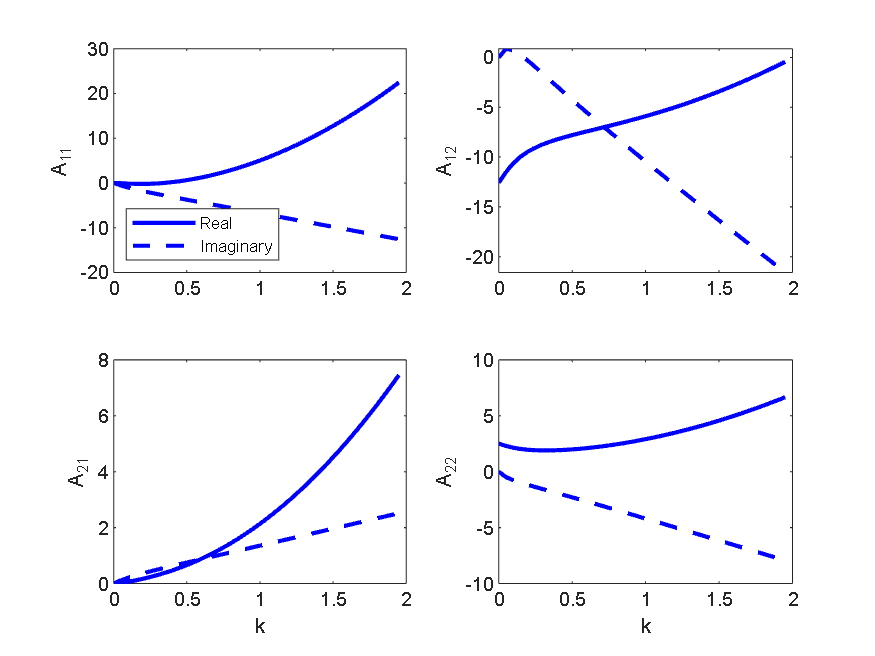

figure
N=40;  % Plot only up to k=2.
subplot(2,2,1)
    plot(GAFk(1:N),real(GAF(1:N,1,1)),'b-','LineWidth',2), hold on
    plot(GAFk(1:N),imag(GAF(1:N,1,1)),'b--','LineWidth',2), ylabel ('A_{11}')
    legend('Real', 'Imaginary','Location','southwest')
subplot(2,2,2)
    plot(GAFk(1:N),real(GAF(1:N,1,2)),'b-','LineWidth',2), hold on
    plot(GAFk(1:N),imag(GAF(1:N,1,2)),'b--','LineWidth',2), ylabel ('A_{12}')
subplot(2,2,3)
    plot(GAFk(1:N),real(GAF(1:N,2,1)),'b-','LineWidth',2), hold on
    plot(GAFk(1:N),imag(GAF(1:N,2,1)),'b--','LineWidth',2), xlabel('k'), ylabel ('A_{21}')
subplot(2,2,4)
    plot(GAFk(1:N),real(GAF(1:N,2,2)),'b-','LineWidth',2), hold on
    plot(GAFk(1:N),imag(GAF(1:N,2,2)),'b--','LineWidth',2), xlabel('k'), ylabel ('A_{22}')

## p-k flutter solution for nominal configuration

In the p-k algorithm, we replace the flutter equation by the solution of

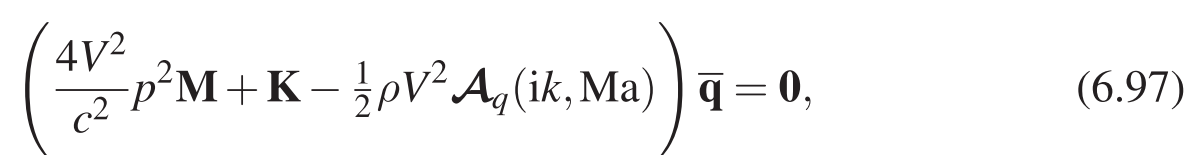

with $p=\gamma k+\mathrm{i}\;k$, such that flutter is the smaller airspeed for which $\gamma =0$.

Vinf=0.1;  Vmax=1.77; Vdelta=0.01;  % Range of velocities to explore.
kappa=sqrt(eig(K,M))*c/(2*Vinf);    % Initial guess of the (nondim) eigs.
Ndof= 2;                            % Number of DoFs.
Tol=1e-3;                           % Convergence tolerance.

% Loop through the airspeeds up the divergence speed.
kv=0;
while (Vinf<=Vmax)
   kv=kv+1;  
   % Loop through the dofs.
   for ke=1:Ndof
       NotConverged=1;
       while NotConverged

           % Interpolate GAF at the current 
           for i1=1:Ndof
             for i2=1:Ndof
               GAFint(i1,i2)=interp1(GAFk,squeeze(GAF(:,i1,i2)), ...
                                     kappa(ke),'makima','extrap');
             end
           end

           % Compute the sqrt of the eigenvalues, enforce positive imag
           % part and sort them by their imaginary part.
           p=sqrt(eig(GAFint*(rho*c^2)/8 - K*(c/(2*Vinf))^2,M));
           p=p.*sign(imag(p));
           [psort,isort]=sort(imag(p));
           p=p(isort);

           % Fixed-point on the current eigenvalue.
           if (abs(imag(p(ke))-kappa(ke)) < Tol)
               NotConverged=0;
           end
           kappa(ke)=imag(p(ke));
       end

       % After convergence, compute the rate of decay.
       gamma(ke,1)= real(p(ke))/imag(p(ke));
   end

   % Store dimensional eigenvalues.
   data.V(kv)=Vinf;
   data.lambda(kv,1:Ndof)=((gamma+i).*kappa)*(2*Vinf/c);
   Vinf=Vinf+Vdelta;
end

Plot eigenvalues.

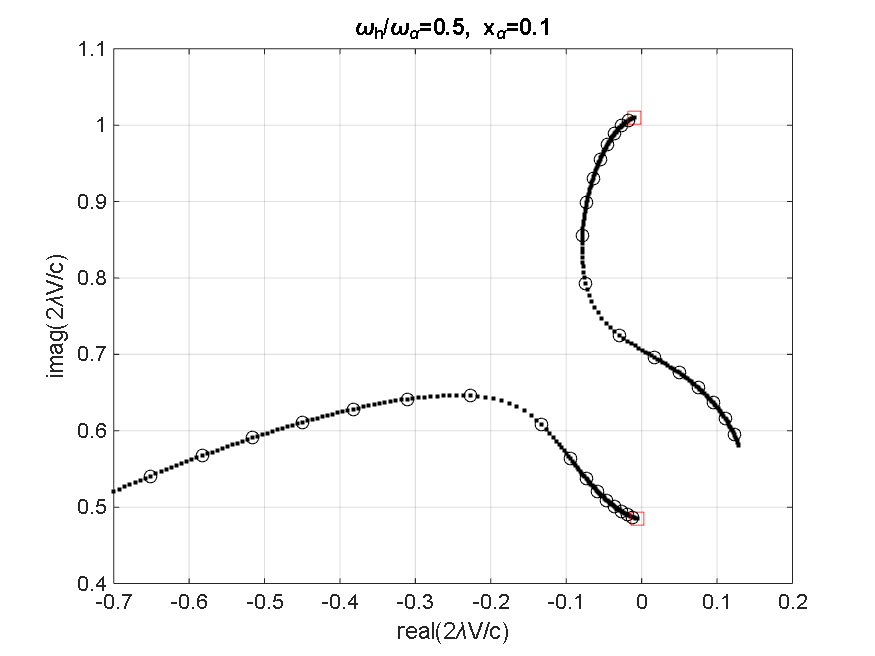

figure
plot(real(data.lambda),imag(data.lambda),'k.'), hold on
xlabel('real(2\lambdaV/c)'), ylabel('imag(2\lambdaV/c)'), grid on
title(['\omega_h/\omega_\alpha=' num2str(omega_ratio1) ', x_\alpha=' num2str(xalpha1)])

% Add big markers at V~Vmin and in increments of 0.1.
plot(real(data.lambda(1,:)),imag(data.lambda(1,:)),'rs','MarkerSize',8)
ii=floor(1/Vdelta)/10;
plot(real(data.lambda(ii:ii:end,:)),imag(data.lambda(ii:ii:end,:)),'ko')

V-g plot.

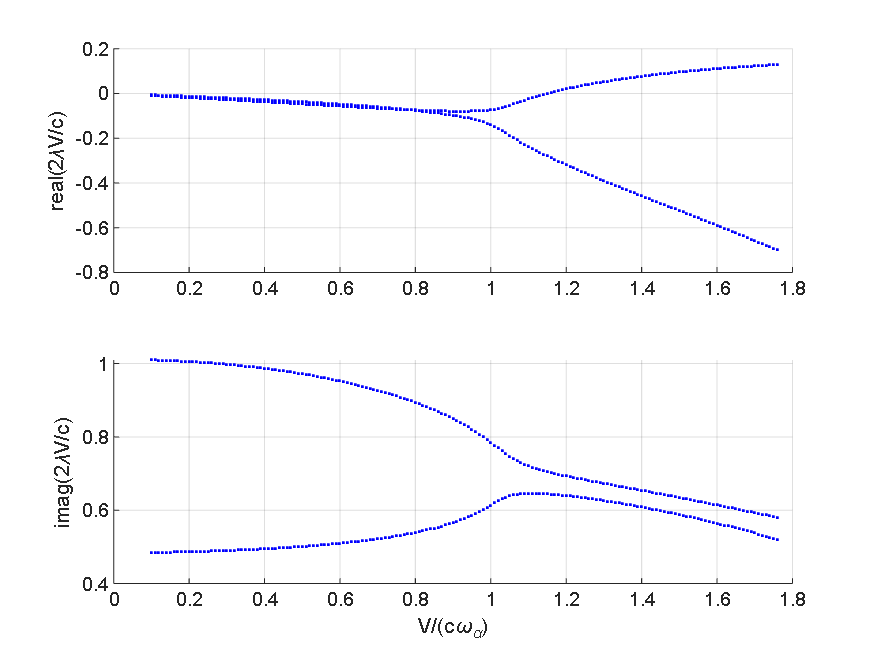

figure
subplot(2,1,1)
    ylabel('real(2\lambdaV/c)')
    grid on, hold on
subplot(2,1,2)
    xlabel('V/(c\omega_\alpha)')
    ylabel('imag(2\lambdaV/c)')
    grid on, hold on
for k=1:2
    subplot(2,1,1), plot(data.V/(c*omega_a),real(data.lambda(:,k)),'b.','MarkerSize',4)
    subplot(2,1,2), plot(data.V/(c*omega_a),imag(data.lambda(:,k)),'b.','MarkerSize',4)
end

## Loop through the parameters in the problem.

Define range of parameters

omega_ratio=0.01:0.01:2;    % Ratio of plunge/pitch typical frequencies.
xalpha=[0 0.05 0.1 0.2];    % Nondimensional position of cg (semichords from x_ea).

Big loop through the matrix generation and p-k solution for each parameter combination. Store flutter speed.

for komega=1:length(omega_ratio)
for kxalpha=1:length(xalpha)

    % Derived parameters:
    x_cg = x_ea+xalpha(kxalpha)*c/2;
    m    = mu*pi*rho*c^2;
    I_a  = m*r_a^2;
    k_a  = I_a*omega_a^2;
    omega_h=omega_ratio(komega)*omega_a;
    k_h  = m * omega_h^2;
    nu_ea=(x_ea-c/2)/(c/2);

    % Aerodynamics influence coefficient matrices:
    CLa0qs=2*pi;
    CLa1qs=2*pi*(1/2-nu_ea);
    CMa1qs=-pi/4;
    CLa1nc=pi;
    CLa2nc=-pi*nu_ea;
    CMa1nc=-pi/4;
    CMa2nc=-pi/4*(1/4-nu_ea);

    % Obtain GAFs.
    A_0 = [[0 CLa0qs];            [0 0]];
    A_1 = [[CLa0qs CLa1qs+CLa1nc];[0 CMa1qs+CMa1nc]];
    A_2 = [[CLa1nc CLa2nc];       [CMa1nc CMa2nc]];
    A_4 = [[CLa0qs CLa1qs];       [0 0]];
   
    kappa_g=2*[[-1 0];[(x_ea-x_ac)/(c/2) 2]];

    jGAF=0;
    for kr=GAFk
        jGAF=jGAF+1;
        GAF(jGAF,:,:)=kappa_g*(theodorsen(kr) * (A_0+i*kr*A_4)+ ...
                               i*kr*(A_1-A_4) - kr^2*A_2);
    end

    % mass matrix, and stiffness matrix:
    M=[[m m*(x_cg-x_ea)/(c/2)];[m*(x_cg-x_ea)/(c/2) I_a/(c^2/4)]];
    K=[[k_h 0];[0 k_a/(c^2/4)]];


% Start p-k solver

    Vinf=0.1;  Vmax=1.77; Vdelta=0.01;  % Range of velocities to explore.
    kappa=sqrt(eig(K,M))*c/(2*Vinf);    % Initial guess of the (nondim) eigs.
    Ndof= 2;                            % Number of DoFs.
    Tol=1e-3;                           % Convergence tolerance.

    % Loop through the airspeeds up the divergence speed.
    kv=0; Vflutter(kxalpha,komega)=1.78;
    while (Vinf<=Vmax) && (Vflutter(kxalpha,komega)==1.78)
       kv=kv+1;  

       % Loop through the dofs.
       for ke=1:Ndof
           NotConverged=1;
           while NotConverged

               % Interpolate GAF at the current 
               for i1=1:Ndof
                 for i2=1:Ndof
                   GAFint(i1,i2)=interp1(GAFk,squeeze(GAF(:,i1,i2)), ...
                                         kappa(ke),'makima','extrap');
                 end
               end

               % Compute the sqrt of the eigenvalues and enforce real imag
               % part and sort them by their imaginary part.
               p=sqrt(eig(GAFint*(rho*c^2)/8 - K*(c/(2*Vinf))^2,M));
               p=p.*sign(imag(p));
               [psort,isort]=sort(imag(p));
               p=p(isort);

               % Fix-point on the current eigenvalue.
               if (abs(imag(p(ke))-kappa(ke)) < Tol)
                   NotConverged=0;
               end
               kappa(ke)=imag(p(ke));
           end

           % After convergence, compute the rate of decay and check for
           % stability.
           gamma(ke,1)= real(p(ke))/imag(p(ke));
           if gamma(ke)>0
               Vflutter(kxalpha,komega)=Vinf;
           end
       end

       Vinf=Vinf+Vdelta;
    end
end
end


Create flutter envelope plot.

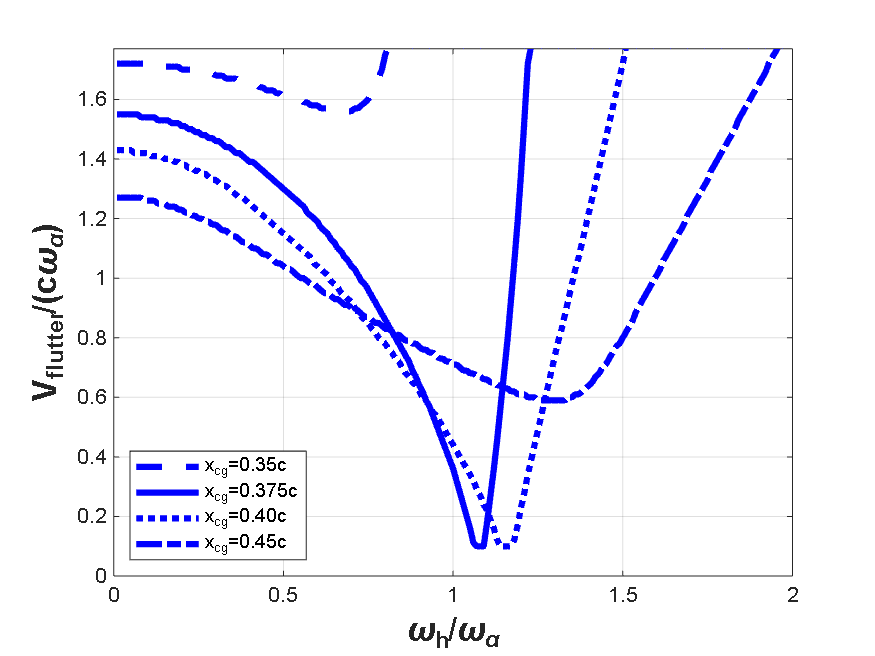

figure
  plot(omega_ratio,Vflutter(1,:),'b--','LineWidth',3), hold on
  plot(omega_ratio,Vflutter(2,:),'b-','LineWidth',3)
  plot(omega_ratio,Vflutter(3,:),'b:','LineWidth',3)
  plot(omega_ratio,Vflutter(4,:),'b-.','LineWidth',3)
  grid on
  xlabel('\omega_h/\omega_\alpha','FontSize',16,'FontWeight','bold')
  ylabel('V_{flutter}/(c\omega_\alpha)','FontSize',16,'FontWeight','bold')
  axis([0 max(omega_ratio) 0 Vmax])
  legend('x_{cg}=0.35c','x_{cg}=0.375c','x_{cg}=0.40c','x_{cg}=0.45c','Location','southwest')